导入数据

shaped_data=reshape(data(1,20,1,:),[1,240])

shaped_data =    -0.6339   -1.0444   -1.0085   -0.5168    0.1005    0.4052    0.1841   -0.3746   -0.8087   -0.7266   -0.1111    0.6570    1.0780    0.9073    0.3402   -0.1331   -0.0910    0.5096    1.3009    1.7589    1.5476    0.7096   -0.4018   -1.3606   -1.8864   -1.9141   -1.5291   -0.8764   -0.1268    0.5167    0.8491    0.7651    0.3629   -0.0669   -0.2133    0.0214    0.4174    0.5783    0.2439   -0.4620   -1.0657   -1.0703   -0.3460    0.7238    1.4771    1.4358    0.6539   -0.3165   -0.8250   -0.5896


数据画图

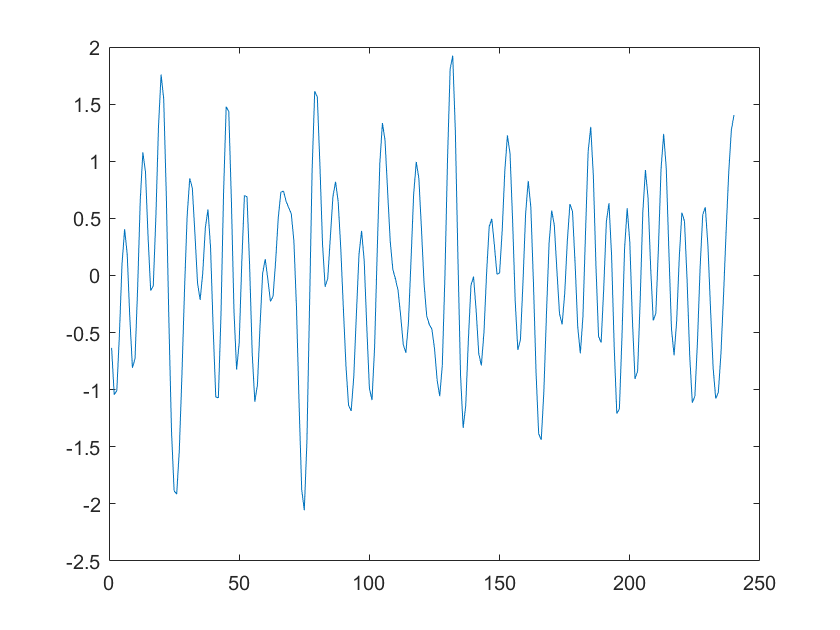

plot(shaped_data)

建立时间表（pentropy的输入数据是时间表的格式，而不是普通数组的格式；输出数据也是如此，得想办法转化）。

time=seconds(linspace(0,1,240))

time = 1×240 duration 数组
           0秒   0.0041841秒   0.0083682秒    0.012552秒    0.016736秒    0.020921秒    0.025105秒    0.029289秒    0.033473秒    0.037657秒    0.041841秒    0.046025秒    0.050209秒    0.054393秒    0.058577秒    0.062762秒    0.066946秒     0.07113秒    0.075314秒    0.079498秒    0.083682秒    0.087866秒     0.09205秒    0.096234秒     0.10042秒      0.1046秒     0.10879秒     0.11297秒     0.11715秒     0.12134秒     0.12552秒     0.12971秒     0.13389秒     0.13808秒     0.14226秒     0.14644秒     0.15063秒     0.15481秒       0.159秒     0.16318秒     0.16736秒     0.17155秒     0.17573秒     0.17992秒      0.1841秒     0.18828秒     0.19247秒     0.19665秒     0.20084秒     0.20502秒     0.20921秒     0.21339秒     0.21757秒     0.22176秒     0.22594秒     0.23013秒     0.23431秒     0.23849秒     0.24268秒     0.24686秒     0.25105秒     0.25523秒     0.25941秒      0.2636秒     0.26778秒     0.27197秒     0.27615秒     0.28033秒     0.28452秒      0.2887秒     0.29289秒     0.29707秒     0.30126秒     0.30544秒     0.30962秒

xt=timetable(time',shaped_data')

xt = 240×1 timetable
       Time          Var1  
    ___________    ________

    0秒            -0.63386
    0.0041841秒     -1.0444
    0.0083682秒     -1.0085
    0.012552秒     -0.51677
    0.016736秒       0.1005
    0.020921秒      0.40519
    0.025105秒       0.1841
    0.029289秒     -0.37463
    0.033473秒     -0.80866
    0.037657秒     -0.72664
    0.041841秒     -0.11112
    0.046025秒      0.65701
    0.050209秒        1.078
    0.054393秒      0.90732
    0.058577秒      0.34022
    0.062762秒      -0.1331


计算谱熵

entropy=pentropy(xt)

entropy = 28×1 timetable
       Time         SE   
    __________    _______

    0.062762秒    0.84642
    0.096234秒    0.82934
    0.12971秒     0.84137
    0.16318秒     0.84619
    0.19665秒     0.85771
    0.23013秒     0.87151
    0.2636秒      0.86949
    0.29707秒     0.83731
    0.33054秒     0.85263
    0.36402秒     0.84272
    0.39749秒     0.85734
    0.43096秒     0.84823
    0.46444秒      0.8227
    0.49791秒     0.84793
    0.53138秒     0.83788
    0.56485秒     0.84537


画图

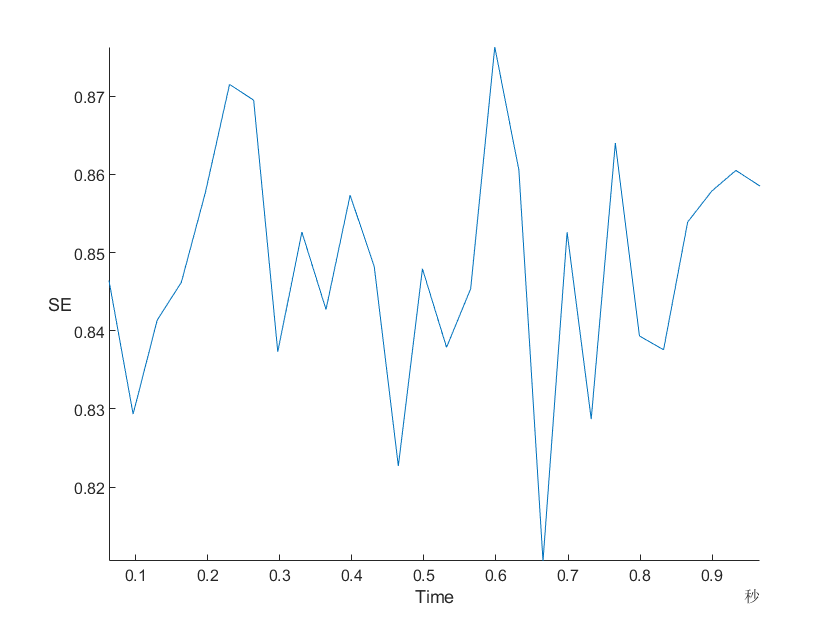

ans =   StackedLineChart - 属性:

         SourceTable: [28×1 timetable]
    DisplayVariables: {'SE'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  显示 所有属性


stackedplot(entropy)